## The Tamari Attractor

clear
clc
close

set(groot, "defaultAxesTickLabelInterpreter", "latex");
set(groot, "defaultTextInterpreter", "latex");
set(groot, "defaultLegendInterpreter", "latex");
set(groot, "defaultColorbarTickLabelInterpreter", "latex");

a = 1.013;
b = -0.011;
c = 0.02;	
d = 0.96;
e = 0.0;
f = 0.01;
g = 1.0;
h = 0.05;
u = 0.05;

odefun = @(t, z) [(z(1) - a * z(2)) * cos(z(3)) - b * z(2) * sin(z(3));
                  (z(1) + c * z(2)) * sin(z(3)) + d * z(2) * cos(z(3));
                   e + f * z(3)+ g * atan((1 - u) / (1 - h) * z(1) * z(2))];

incond = [1 1 1];
timeint = [0 300];
tau = 0.01;

[t, zsol, dzdt_eval] = odeExplicitSolvers(odefun, timeint, tau, incond, "Method", "RKB6");

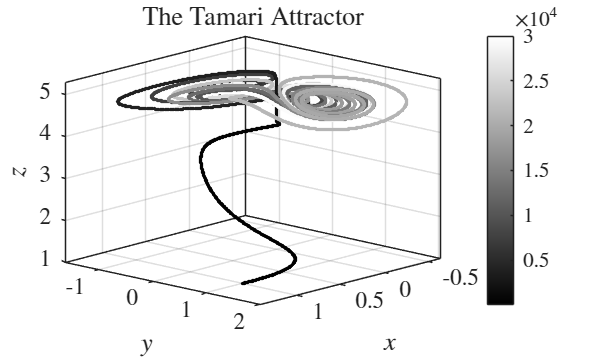

figure();
scatter3(zsol(:,1), zsol(:,2), zsol(:,3),4, 1:numel(t), 'filled');
colormap gray;
colorbar;
axis tight;
grid on;
box on;
view([-227.35 19.42])
xlabel('$x$');
ylabel('$y$');
zlabel('$z$');
title('The Tamari Attractor');
set(gca, "FontSize", 14)

% exportgraphics(gcf, "The_Tamari_Attractor.png", "Resolution", 600)